# Simple ordinary differential equation

This script demonstrates how you can solve a simple ordinary differential equation with a given initial condition in Matlab.

## Ordinary differential equations

In mathematics, an **ordinary differential equation** (**ODE**) is a [differential equation](https://en.wikipedia.org/wiki/Differential_equation) containing one or more functions of one [independent variable](https://en.wikipedia.org/wiki/Independent_variable) and the [derivatives](https://en.wikipedia.org/wiki/Derivative) of those functions. The term *ordinary* is used in contrast with the term [partial differential equation](https://en.wikipedia.org/wiki/Partial_differential_equation) which may be with respect to *more than* one independent variable.

### General definition

Let $y$ be a dependent variable and *x* an independent variable, and $y = f(x)$ is an unknown function in question. Given $F$, a function of $x$,$y$ and derivatives of$y$. Then an equation of the form:


$$F(x,y(x),y'(x),..., y^{(n-1)}(x)) = y^{(n)}(x)$$


is called an explicit ordinary differential equation of order $n$. More generally, an implicit ordinary differential equation of order $n$ takes the form:

$F(x,y(x),y'(x),..., y^{(n-1)}(x), y^{(n)}(x)) = 0$.

### Initial value problem

In multivariable calculus, an initial value problem (IVP) is **an ordinary differential equation together with an initial condition **$y_0 = f(x_0)$ **which specifies the value of the unknown function at a given point in the domain**. Modeling a system in physics or other sciences frequently amounts to solving an initial value problem.

## Solving initial value problem

Let's see how the following example of an initial value problem could be solved in Matlab:


$$y(x) =? \\
y'(x) = x, \quad y(0) = x_0 = 10$$


The exact solution:


$$y(x) = \frac{x^2}{2} + C, \quad C\in \mathbf{R} \\
y(0) = \frac{0^2}{2} + C = 10, \quad C = 10 \\
y(x) = \frac{x^2}{2} + 10$$


### Inputs

#### Solution interval

The interval of the solution (e.g., time interval)

xStart = 0;
xEnd = 10;

#### Initial condition

Initial value `y(xStart) = y0`

y0 = 10;

### Solving the intial value problem

In Matlab, initial value problems can be solved by different [`ode`](https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html) functions. 

The differential equation can be given by a function handle that represents the explicit definition of the differential equation.

diffEquationFcnHandle = @(x, y) x;

In Matlab, only first-order differential equations can be solved by ode functions. However, any explicit differential equaion of order $n$ [can be reshaped to a first-order system](https://en.wikipedia.org/wiki/Ordinary_differential_equation#Reduction_to_a_first-order_system).

Solving the initial value problem with [`ode45`](https://www.mathworks.com/help/matlab/ref/ode45.html) solver that performs the most common Runge-Kutta numerical method:

[xVect, yVect] = ode45(diffEquationFcnHandle, [xStart, xEnd], y0);

## Plotting the results

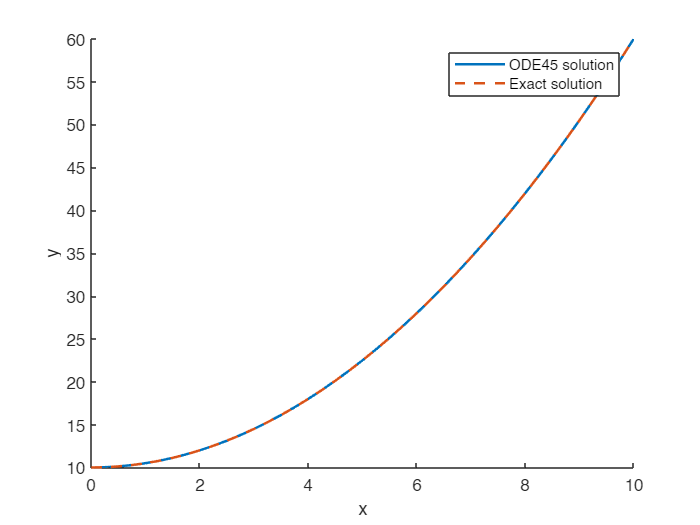

fig = figure();
ax = axes(fig);
hold(ax, 'on');
plot(ax, xVect, yVect, 'LineWidth', 1.5);
plot(ax, xVect, xVect.^2/2 + 10, 'LineWidth', 1.5, 'LineStyle', '--');
xlabel('x')
ylabel('y')
legend('ODE45 solution', 'Exact solution')
hold(ax, 'off');